# Map Estimation

See ... for the model building and parameter inferance.

## 1. Load data

clear all; load('data/dc_corr.mat'); load coastlines; addpath('../functions/'); load('data/Density_modelInf.mat')

## 2. Initialization of the grid

g.lat=43:.2:68;
g.lon=-5:.2:30;
g.time = start_date-1:1/24/4:end_date-1;
g.atime=unique(round(datenum(g.time)));

g.nlat=numel(g.lat);
g.nlon=numel(g.lon);
g.nl=numel(g.lat)*numel(g.lon);
g.nt=numel(g.time);
g.nat=numel(g.atime);

[g.lat3D,g.lon3D,g.time3D]=ndgrid(g.lat,g.lon,g.time);
[g.lat2D, g.lon2D] = ndgrid(g.lat,g.lon);

## 3. Mask

Mask water

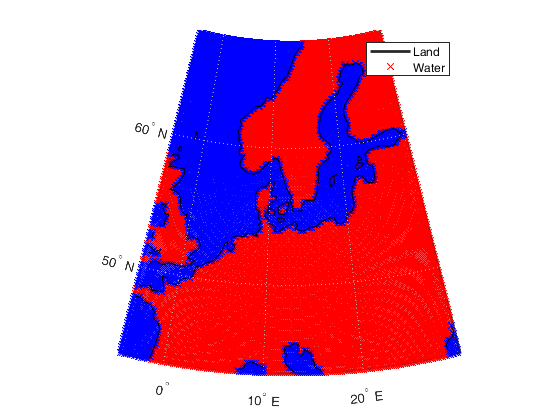

g.mask_water = inpolygon(g.lat2D,g.lon2D,coastlat,coastlon);

figure; hold on; 
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(g.lat2D(g.mask_water),g.lon2D(g.mask_water),'xr')
plotm(g.lat2D(~g.mask_water),g.lon2D(~g.mask_water),'xb')
plotm(coastlat, coastlon,'k')
legend({'Land','Water'})

Mask distance Radar

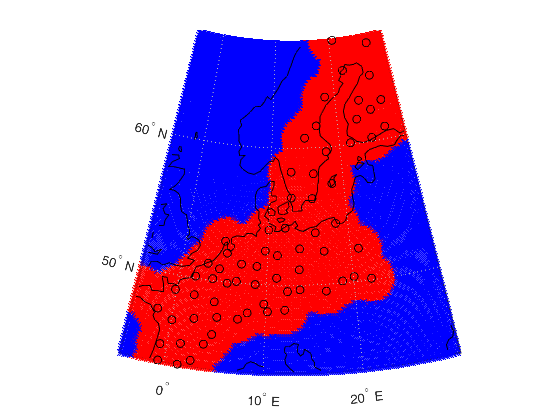

gDdist_sf = pdist2([[dc.lat]' [dc.lon]'], [g.lat2D(:) g.lon2D(:)], @lldistkm);
g.mask_distrad = reshape(min(gDdist_sf)<ampli.cov.parm(3)*1.2,size(g.lat2D));

g.latlonmask = (g.mask_water &  g.mask_distrad);
g.nlm = sum(g.latlonmask(:));

figure; hold on; 
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(g.lat2D(g.mask_distrad),g.lon2D(g.mask_distrad),'xr')
plotm(g.lat2D(~g.mask_distrad),g.lon2D(~g.mask_distrad),'xb')
plotm([dc.lat]', [dc.lon]','ok')
plotm(coastlat, coastlon,'k')

Sunrise and sunset

load('./data/sunrisesunset_grid.mat')

g.sunrise = nan(g.nlat,g.nlon,g.nt);
g.sunset = g.sunrise;
for i_t=2:numel(tim_d)
    id = g.time>tim_d(i_t)-1 & g.time<=tim_d(i_t);
    
    F=griddedInterpolant({lat_d,lon_d},sunrs_e(:,:,i_t-1));
    g.sunset(:,:,id)=repmat(F(g.lat2D,g.lon2D),1,1,sum(id));
    
    F=griddedInterpolant({lat_d,lon_d},sunrs_b(:,:,i_t));
    g.sunrise(:,:,id)=repmat(F(g.lat2D,g.lon2D),1,1,sum(id));
    
end

% figure('position',[0 0 1000 400]); hold on;
% plot(g.time(:),reshape(mean(mean(g.sunset,1),2),1,2017))
% plot(g.time(:),reshape(mean(mean(g.sunrise,1),2),1,2017))
% legend('sunset','sunrise')

Score time of night

g.scoret = (datenum(g.time3D)-mean(cat(4,g.sunrise,g.sunset),4)) ./ (g.sunrise-g.sunset)*2;
g.scoret(g.scoret<-1.1)=-1.1;
g.scoret(g.scoret>1.1)=1.1;

% filename='data/';
% Frame(numel(g.time)-1) = struct('cdata',[],'colormap',[]); 
% fig=figure(2);
% worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
% hcoast=plotm(coastlat, coastlon,'k'); hsurf=[];
% for i_t = 1:numel(g.time)-1
%     delete(hsurf);
%     hsurf=surfm(g.lat2D,g.lon2D,g.scoret(:,:,i_t));
%     uistack(hcoast,'top')
%     title(datestr(g.time(i_t))); caxis([-1 1]); drawnow;
%     Frame(i_t) = getframe(fig);
%     [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
%     if i_t == 1
%         imwrite(imind,cm,[filename '.gif'],'gif', 'Loopcount',inf);
%     else
%         imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append');
%     end
% end
% v=VideoWriter([filename '.avi']);
% v.FrameRate = 4;
% v.Quality = 75;
% open(v);
% writeVideo(v, Frame);
% close(v);

% figure;
% plot(g.time3D(:), g.scoret(:), '.k' )

Mask of the day

g.mask_day =  g.scoret>-1 & g.scoret<1;

Group g.time by night

[~,g.dateradar] = ismember(round(datenum(reshape(g.sunrise(1,1,:),numel(g.time),1))),g.atime);
g.dateradar(g.dateradar==0)=1;

Mask Rain

% rain = []
% for i_d=1:numel(dc)
%     id=dc(i_d).scoret<1&dc(i_d).scoret>-1;
%     rain=[rain; repmat(i_d,sum(id),1) dc(i_d).denss(id), dc(i_d).tcrw(id)];
% end
% 
% figure; hold on;
% gscatter(rain(:,2), rain(:,3), rain(:,1))
% 
% figure; hold on; plot(rain(:,2)); yyaxis right; plot(rain(:,3))
% 
% % histogram of rain
% histogram(log10(rain(:,3)))
% 
% histogram(log10(rain(:,2)))
% 
% % Compare histogram of rain vs no rain
% id=rain(:,3)<10^-8;
% figure; hold on;
% histogram((rain(id,2)))
% histogram((rain(~id,2)))
% legend('no Rain','Rain')
% 
% VAL=0:0.001:0.1;
% r=nan(size(VAL));
% r2=nan(size(VAL));
% r3=nan(size(VAL));
% for i_val=1:numel(VAL)
%     id=rain(:,3)>VAL(i_val);
%     r(i_val)=mean(rain(id,2)==0);
%     r2(i_val)=mean(rain(~id,2)==0);
%     r3(i_val)=sum(id);
% end
% figure; hold on; plot(VAL,r);plot(VAL,r2); 
%  yyaxis right; plot(VAL,r3); 
% xlabel('threashold'); ylabel('percent of 0 value');
% legend('in removed data','in kept data')

% Threashold of 0.03 (0.02-0.05)
g.mask_rain_thr=0.03;
load('data/Rain_grid.mat','TCRW');
g.mask_rain=TCRW<0.03;

Clear the masking variable

clear sunrs_b sunrs_e tim_d lat_d lon_d F 

## 6.2 Amplitude Kriging

Built ampli.cov.parmriance of the radar data

gampli.Ddist_sf = pdist2(repmat([[dc.lat]' [dc.lon]'], g.nat,1), [g.lat2D(:) g.lon2D(:)], @lldistkm);
gampli.Dtime_sf = pdist2(repelem(g.atime',numel(dc),1), g.atime');
gampli.Dtime_sf = gampli.Dtime_sf(~ampli.isnanA,:);
gampli.Ddist_sf = gampli.Ddist_sf(~ampli.isnanA,:);
ampli_An = ampli.An(~ampli.isnanA);

Initialized the simulated grid

gampli.An_est=nan(g.nat,g.nl);
gampli.An_sig=gampli.An_est;

Perform the kriging

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

wradius=2;
latlonmask = find(g.latlonmask);

for i_l=1:g.nlm
    id1=find(gampli.Ddist_sf(:,latlonmask(i_l))<ampli.cov.parm(3)*wradius);
    for i_t=1:g.nat
         id2= id1(gampli.Dtime_sf(id1,i_t)<ampli.cov.parm(4)*wradius);
         Cab = ampli.cov.parm(2).*Gneiting(gampli.Ddist_sf(id2,latlonmask(i_l)), gampli.Dtime_sf(id2,i_t), ampli.cov.parm(3), ampli.cov.parm(4), ampli.cov.parm(5), ampli.cov.parm(6), ampli.cov.parm(7));
         lambda = ampli.cov.C(id2,id2)  \  Cab;
        
        gampli.An_est(i_t,latlonmask(i_l)) = lambda' * ampli_An(id2);
        gampli.An_sig(i_t,latlonmask(i_l)) = sqrt(ampli.cov.parm(1) + ampli.cov.parm(2) - lambda' * Cab);
        assert(~isnan(gampli.An_est(i_t,latlonmask(i_l))))
    end
end

gampli.An_est=reshape(gampli.An_est',g.nlat,g.nlon,g.nat);
gampli.An_sig=reshape(gampli.An_sig',g.nlat,g.nlon,g.nat);

Figure

% figure('position',[0 0 1000 600]); 
% for i_t = 1:g.nat-1
%     subplot(4,6,i_t); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
%     surfm(g.lat2D,g.lon2D,gampli.An_est(:,:,i_t))
%     %scatterm([dc.lat],[dc.lon],[],ampli.An(:,i_t),'filled','MarkerEdgeColor','k')
%     plotm(coastlat, coastlon,'k')
% end

## 3.5 Back-transform

gampli.A_est = gampli.An_est*ampli.ns.std;
gampli.A_sig = sqrt(gampli.An_sig.^2 * ampli.ns.std.^2);

figure('position',[0 0 1000 600]); 
for i_t = 1:g.nat-1
    subplot(4,6,i_t); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);
    surfm(g.lat2D,g.lon2D,gampli.A_est(:,:,i_t))
    scatterm([dc.lat],[dc.lon],[],ampli.A(:,i_t),'filled','MarkerEdgeColor','k')
    plotm(coastlat, coastlon,'k')
end

Figure

filename='data/Density_estimationMap_amplitude';
Frame(numel(g.atime)-1) = struct('cdata',[],'colormap',[]); 
fig=figure(2);
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
hcoast=plotm(coastlat, coastlon,'k'); hsurf=[];hscat=[];
for i_t = 1:numel(g.atime)-1
    delete(hsurf); delete(hscat)
    hsurf=surfm(g.lat2D,g.lon2D,gampli.A_est(:,:,i_t));
    hscat=scatterm([dc.lat],[dc.lon],[],ampli.A(:,i_t),'filled','MarkerEdgeColor','k');
    uistack(hcoast,'top')
    title(datestr(g.atime(i_t))); caxis([-.3 .3]); drawnow;
    Frame(i_t) = getframe(fig);
    [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
    if i_t == 1
        imwrite(imind,cm,[filename '.gif'],'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append');
    end
end
v=VideoWriter([filename '.avi']);

v.FrameRate = 4;
v.Quality = 75;
open(v);
writeVideo(v, Frame);

Error using VideoWriter/writeVideo (line 402)
The 'cdata' field of FRAME must not be empty

close(v);

## 6.3 Residu Kriging

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

gtimenum=datenum(g.time);
res_cov_parm=res.cov.parm;
g_mask_day=reshape(g.mask_day,g.nl,[]);
g_dateradar=g.dateradar;
ndc = numel(dc);


gDdist_sf = pdist2([[dc.lat]' [dc.lon]'], [g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)], @lldistkm);
g_mask_day = g_mask_day(latlonmask(:),:)';

wradius=2;

gres_rn_est=cell(g.nat,1);
gres_rn_sig=gres_rn_est;
neighday=cell(g.nat,1);
sim=neighday;
res_cov_C=cell(g.nat,1);
res_rn=cell(g.nat,1);
for i_d=1:g.nat
    neighday{i_d}  = find(ismember( data.dateradar, (i_d-1)*ndc+(1:ndc)));
    res_cov_C{i_d} = res.cov.C(neighday{i_d},neighday{i_d});
    res_rn{i_d} =  res.rn(neighday{i_d});
    sim{i_d} = find(g_dateradar==i_d);
    gres_rn_est{i_d} = nan(g.nlm,numel(sim{i_d}));
    gres_rn_sig{i_d} = gres_rn_est{i_d};
end

% maxNumCompThreads('automatic');
% parpool(maxNumCompThreads());

for i_d=1:g.nat
   %maxNumCompThreads(1);
    for i_l=1:g.nlm
        tmpD = gDdist_sf(data.i_r(neighday{i_d}),i_l);
        neighloc = find(tmpD<res_cov_parm(3)*wradius);
        tmpD=tmpD(neighloc);
        simloc = find(g_mask_day(sim{i_d},i_l));
        for i_sd=1:numel(simloc)
            tmpT = abs(data.time(neighday{i_d}(neighloc))-gtimenum(sim{i_d}(simloc(i_sd))));
            tmpidT = tmpT<res_cov_parm(4)*wradius;
            neighhour = neighloc(tmpidT);
            if isempty(neighhour)
                gres_rn_est{i_d}(i_l,simloc(i_sd)) = 0;
                gres_rn_sig{i_d}(i_l,simloc(i_sd)) = res_cov_parm(1) + res_cov_parm(2);
            else
                Cab = res_cov_parm(2).*Gneiting(tmpD(tmpidT), tmpT(tmpidT), res_cov_parm(3), res_cov_parm(4), res_cov_parm(5), res_cov_parm(6), res_cov_parm(7));
                lambda = res_cov_C{i_d}(neighhour,neighhour)  \  Cab;
                gres_rn_est{i_d}(i_l,simloc(i_sd)) = lambda' * res_rn{i_d}(neighhour);
                gres_rn_sig{i_d}(i_l,simloc(i_sd)) = sqrt(res_cov_parm(1) + res_cov_parm(2) - lambda' * Cab);
            end
        end
    end
end

gres.rn_est=nan(g.nlat,g.nlon,g.nt);
gres.rn_sig=gres.rn_est;

[latmask, lonmask]=ind2sub([g.nlat g.nlon],latlonmask);
for i_d=1:g.nat
    id = sub2ind([g.nlat g.nlon g.nt], repmat(latmask,numel(sim{i_d}),1), repmat(lonmask,numel(sim{i_d}),1), repelem(sim{i_d},g.nlm));
    gres.rn_est(id) = gres_rn_est{i_d}(:);
    gres.rn_sig(id) = gres_rn_sig{i_d}(:);
end

Back-transform

gres.r_est = gres.rn_est.*res.ns.std(g.scoret);
gres.r_sig = sqrt(gres.rn_sig.^2.*res.ns.std(g.scoret).^2);

Figure

filename='data/Density_estimationMap_residu';
mask_fullday = find(~reshape(all(all(isnan(gres.rn_est),1),2),g.nt,1));
Frame(numel(mask_fullday)-1) = struct('cdata',[],'colormap',[]);

fig=figure(2);
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
hcoast=plotm(coastlat, coastlon,'k'); hsurf=[]; hscat=[];
for i_t = 1:numel(mask_fullday)
    delete(hsurf); delete(hscat);
    hsurf=surfm(g.lat2D,g.lon2D,gres.r_est(:,:,mask_fullday(i_t)));
    gtit = datenum(g.time(mask_fullday(i_t)+([-1 0 1])));
    id = find(mean(gtit(1:2))<data.time & mean(gtit(2:3))>data.time);
    if sum(id)>0
        G = findgroups(data.dateradar(id));
        hscat=scatterm(splitapply(@mean,data.lat(id),G),splitapply(@mean,data.lon(id),G),[],splitapply(@mean,res.r(id),G),'filled','MarkerEdgeColor','k');
    end
    uistack(hcoast,'top');
    caxis([-.26 .27])
    title(datestr(g.time(mask_fullday(i_t)))); drawnow
    Frame(i_t) = getframe(fig);
    [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
    if i_t == 1
        imwrite(imind,cm,[filename '.gif'],'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append');
    end
end
v=VideoWriter([filename '.avi']);
v.FrameRate = 4;
v.Quality = 75;
open(v);
writeVideo(v, Frame);
close(v);

## 6.4 Reassemble

t = g.lat3D.*trend.p(1)+trend.p(2);
A = gampli.A_est(:,:,g.dateradar);
p = polyval(curve.p,g.scoret);

g.denstrans_est = t + A + p + gres.r_est;
g.dens_est = (g.denstrans_est).^(1/pow_a);

g.denstrans_sig = sqrt(gampli.A_sig(:,:,g.dateradar).^2 + gres.r_sig.^2);

g.dens_q10 = ( g.denstrans_est+norminv(.1).*g.denstrans_sig ).^(1/pow_a);
g.dens_q90 = ( g.denstrans_est+norminv(.9).*g.denstrans_sig ).^(1/pow_a);


Figure

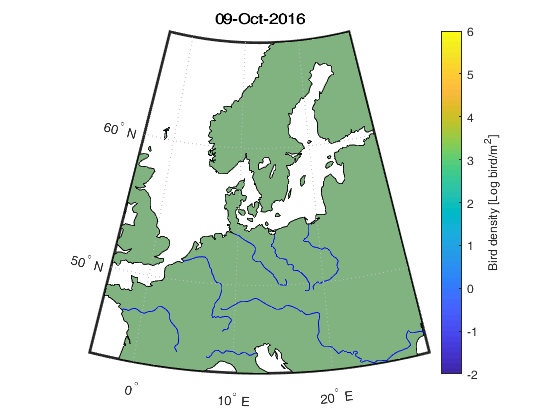

Error using matlab.graphics.primitive.Line/get
Invalid or deleted object.

Error in uistack (line 65)
Parent = get(Handles, {'Parent'});

fig=figure(2);  
filename='data/Density_estimationMap_reassamble_05102016';
mask_fullday = find(~reshape(all(all(isnan(g.dens_est),1),2),g.nt,1));
mask_fullday = 1553:1609;
Frame(numel(mask_fullday)-1) = struct('cdata',[],'colormap',[]); 
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
geoshow('landareas.shp', 'FaceColor', [0.5 0.7 0.5])
geoshow('worldrivers.shp','Color', 'blue')
set(gcf,'color','w'); %hcoast=plotm(coastlat, coastlon,'k');
 hsurf=[]; hscat=[];
caxis([-2 6]); c=colorbar;c.Label.String = 'Bird density [Log bird/m^2]';
for i_t = 1:numel(mask_fullday)
    
    hsurf=surfm(g.lat2D,g.lon2D,log(g.dens_est(:,:,mask_fullday(i_t))));
    gtit = datenum(g.time(mask_fullday(i_t)+([-1 0 1])));
    id = find(mean(gtit(1:2))<data.time & mean(gtit(2:3))>data.time);
%     if sum(id)>0
%         G = findgroups(data.dateradar(id));
%         hscat=scatterm(splitapply(@mean,data.lat(id),G),splitapply(@mean,data.lon(id),G),[],splitapply(@mean,log(data.dens(id)),G),'filled','MarkerEdgeColor','k');
%     end
    % uistack(hcoast,'top');
    title(datestr(g.time(mask_fullday(i_t)))); drawnow;

    Frame(i_t) = getframe(fig);
    [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
    if i_t == 1
        imwrite(imind,cm,[filename '.gif'],'gif', 'Loopcount',inf,'DelayTime',0.1);
    else
        imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append','DelayTime',0.1);
    end
    delete(hsurf);% delete(hscat);
end


v=VideoWriter([filename '.avi']);
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, Frame);
close(v);

Save

save('data/Density_estimationMap','g','gampli','gres','-v7.3')
% load('data/Density_estimationMap')